close all
clearvars

% 1. Duomenų paruošimas
x = 0.1:1/22:1;
d = ((1 + 0.6*sin(2*pi*x/0.7)) + 0.3*sin(2*pi*x))/2;
figure(1)
plot(x, d)

% 2. Tinklo struktūros pasirinkimas
% RBF
% Pasleptajame sluoksnyje aktyvavimo Gausine RBF, išėjimo sluoksnyje - tiesinė

% Apskaičiuoti maksimumų (ekstremų) skaičių
localMaxCnt = 0;
for indx = 2:(length(d)-1)
    if d(indx) > d(indx - 1) && d(indx) > d(indx + 1)
            localMaxCnt = localMaxCnt + 1;
    end
end

% Apskaičiuoti centrų pozicijas
centers = zeros(1, localMaxCnt);
centerNum = 0;
for indx = 2:(length(d)-1)
    if d(indx) > d(indx - 1) && d(indx) > d(indx + 1)
        centerNum = centerNum + 1;
        centers(centerNum) = x(indx);
    end
end
disp('centrai:')

centrai:


disp(centers)

    0.1909    0.9182




% Apskaičiuoti spindulius:
% Centrai yra tik 2, todėl spinduliai bus tokie patys
r1 = (abs(centers(1) - centers(2))) / (2*sqrt(2));
r2 = r1;
disp('spinduliai:')

spinduliai:


disp(r1)

    0.2571




% 3. Pradinių parametrų pasirinkimas
w1 = randn(1);  w2 = randn(1);  w0 = randn(1);

eta = 0.11;
e_arr = zeros(1, length(x));
e_sum = inf;
cycle_num = 0;

% 4. Tinklo atsako skaičiavimas
while (e_sum/length(x) > 0.025 && cycle_num < 1000000)
    cycle_num = cycle_num + 1;
    e_arr = zeros(1,length(x));
    for indx = 1:length(x)
        % I sluoksnis
        %Pasvertos sumos:
        v1 = exp(-(x(indx) - centers(1))^2 / (2*r1^2));
        v2 = exp(-(x(indx) - centers(2))^2 / (2*r2^2));

        % Išėjimai:
        y = w1*v1 + w2*v2 + w0;

        % Klaidos skaičiavimas
        e = d(indx) - y;
        e_arr(indx) = d(indx) - y;
        % delta_out = aktyvavimo_funkcijos_išvestinė|v * tikslo_funkcijos_išvestinė|e
        % tikslo f-ja 1/2 e^2
        % delta_hidden = aktyvavimo_funkcijos_išvestinė|v * (w1*delta_out1 + w2*delta_out2 + ...) 
        %delta_out = e; % Nes (d fi) / (d e) = 1 * 1/2 * 2 * e
  
        % Svorių naujinimas
        w1 = w1 + eta*e_arr(indx)*v1;
        w2 = w2 + eta*e_arr(indx)*v2;
        w0 = w0 + eta*e;
    end
    e_sum = sum(abs(e_arr));
end
% Tikriname apmokytą algoritmą
x_in = 0.1:1/66:1;
Y_out = zeros(1, length(x_in));
e = 0;

d_out = ((1 + 0.6*sin(2*pi*x_in/0.7)) + 0.3*sin(2*pi*x_in))/2;

for indx = 1:length(x_in)
        % I sluoksnis
        v1 = exp(-(x_in(indx) - centers(1))^2 / (2*r1^2));
        v2 = exp(-(x_in(indx) - centers(2))^2 / (2*r2^2));

        % Išėjimai:
        y = w1*v1 + w2*v2 + w0;
        Y_out(indx) = y;

        % Klaidos skaičiavimas
        e = e + abs(d_out(indx) - y);
end

e = e/length(x_in);
disp('Vidutine klaida:')

Vidutine klaida:


disp(e)

    0.0239



disp('Mokymo ciklu skaicius:')

Mokymo ciklu skaicius:


disp(cycle_num)

   388



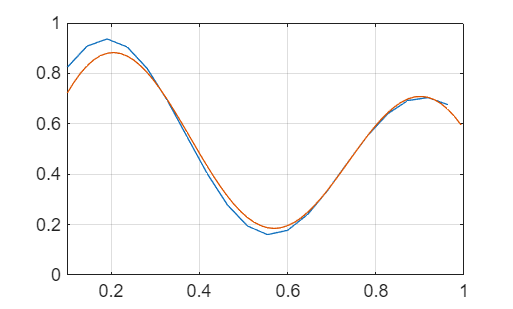

hold on
plot(x_in, Y_out)
xlim([0.1 1])
grid on